% Define the center and radius of the circle
x0 = 0;
y0 = 0;
r = 1;

U1 = @(x,y) zeta*sqrt((x - goal(1)).^2 + (y - goal(2)).^2);
% Create x and y values that span the range of the circle
x_values = linspace(x0-r, x0+r, 100);
y_values = linspace(y0-r, y0+r, 100);

% Create a meshgrid using the x and y values
[X, Y] = meshgrid(x_values, y_values);

% Create a logical matrix that represents the points inside the circle
logical_matrix = (X-x0).^2 + (Y-y0).^2 <= r^2;

% Use the logical matrix to filter the meshgrid and only keep the points inside the circle
X = X(logical_matrix);
Y = Y(logical_matrix);

Z = U1(X,Y);
gradient(-Z)

ans =     0.1180
    0.1179
    0.1177
    0.1175
    0.1172
    0.1170
    0.1168
    0.1166
    0.1163
    0.1161


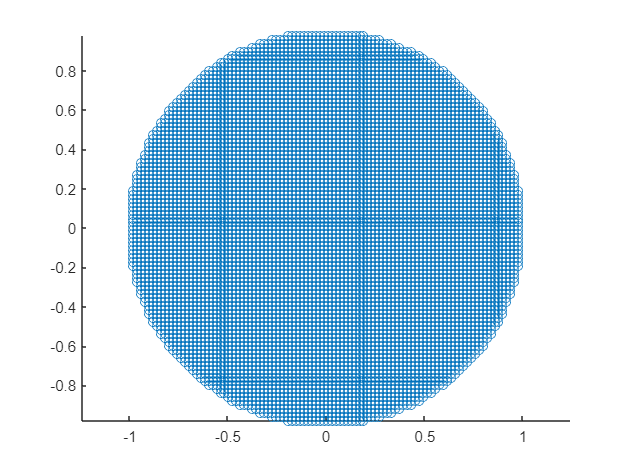

% Plot the points inside the circle
scatter(X(:), Y(:));
axis equal;